**Physics 434: Application of Computers to Physical Measurement **

**11.21.19 **

**Author: Avi Soval **

**Collaborators: Jeff Jiang, Thomas Conaway **

#### **Lab 7: Event Selection Optimization for LHC Data **

**We continue our exploration of the LHC data with a strong QCD background. With our dedicated training sets of confirmed Higgs jets, we want to 'cut' or trim the background QCD data such that the signal-to-noise ratio for this background is maximized. **

h5disp("higgs_100000_pt_250_500.h5"); 

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp('qcd_100000_pt_250_500.h5'); 

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000



higgs = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500'); 
qcd = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500'); 

higgs = array2table(higgs,'RowNames',{'pt';'eta';'phi';'mass';'ee2';'ee3';'d2';'angularity';'t1';'t2';'t3';'t21';'t32';'KtDeltaR'}); 
qcd = array2table(qcd,'RowNames',{'pt';'eta';'phi';'mass';'ee2';'ee3';'d2';'angularity';'t1';'t2';'t3';'t21';'t32';'KtDeltaR'}); 

VariableNames = ["Transverse Momentum (GeV)";"Pseudorapidity";"Azimuthal Angle (rad)";"Invariant Mass";"2-Point ECF Ratio";"3-Point ECF Ratio";"3 to 2 Point ECF Ratio";"Angularity";"t1";"t2";"t3";"t21";"t32";"KtDeltaR"]; 

**First, we plot histograms of the Higgs and QCD invariant mass data, properly normalized to 1. **

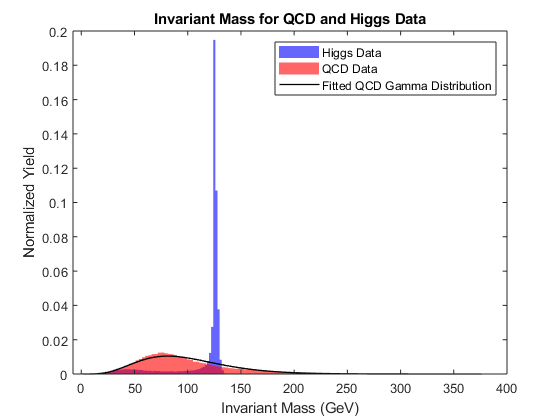

figure(1)
h1 = histogram(higgs{4,:},"EdgeColor",'none',"Normalization",'pdf','FaceColor','blue'); 
hold on 
h2 = histogram(qcd{4,:},"EdgeColor",'none',"Normalization",'pdf','FaceColor','red'); 
hold on 
background = fitdist(qcd{4,:}.','Gamma'); 
x = 0:375; 
plot(pdf(background,x),'LineWidth',1,'Color','black'); 
xlabel('Invariant Mass (GeV)'); 
ylabel('Normalized Yield'); 
title('Invariant Mass for QCD and Higgs Data'); /*-legend('Higgs Data','QCD Data','Fitted QCD Gamma Distribution');  

**By fitting a Gamma distribution to the QCD background, we can calculate the significance of the 125 GeV Higgs detection. **

prob = cdf(background,125,'upper'); 
sigma = norminv(prob); 
disp("The 125 GeV Higgs spike has a sigma of " + abs(sigma))

The 125 GeV Higgs spike has a sigma of 0.74368


**Now, we re-normalize the Higgs and QCD histograms to the expected yields specified in the dataset documentation. For this data, the expected yields for **$N_{Higgs}$ **= 100 and **$N_{QCD}
$ **= 20,000. By doing this, we can compare the properly normalized area under each histogram and find an appropriate signal-to-noise ratio. This ratio will change as we make different cuts to the data, and finding the optimum value of this ratio is therefore our primary goal. **

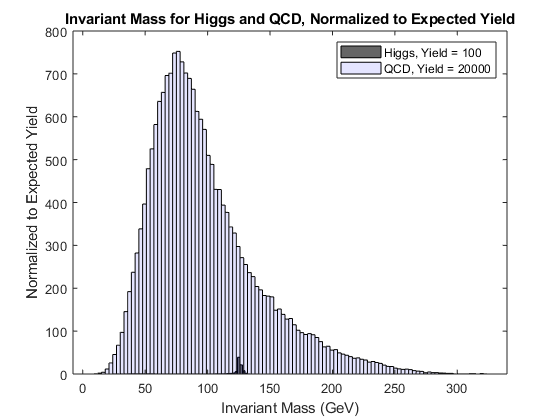

higgs_edges = h1.BinEdges; 
higgs_counts = h1.BinCounts/sum(h1.BinCounts) * 100; 

qcd_edges = h2.BinEdges; 
qcd_counts = h2.BinCounts/sum(h2.BinCounts) * 20000; 

figure(2)
histogram('BinEdges',higgs_edges,'BinCounts',higgs_counts,'FaceColor','black'); 
hold on
histogram('BinEdges',qcd_edges,'BinCounts',qcd_counts,'FaceColor','blue','FaceAlpha',0.1);
xlabel('Invariant Mass (GeV)'); 
ylabel('Normalized to Expected Yield'); 
title('Invariant Mass for Higgs and QCD, Normalized to Expected Yield'); 
legend('Higgs, Yield = 100','QCD, Yield = 20000'); 